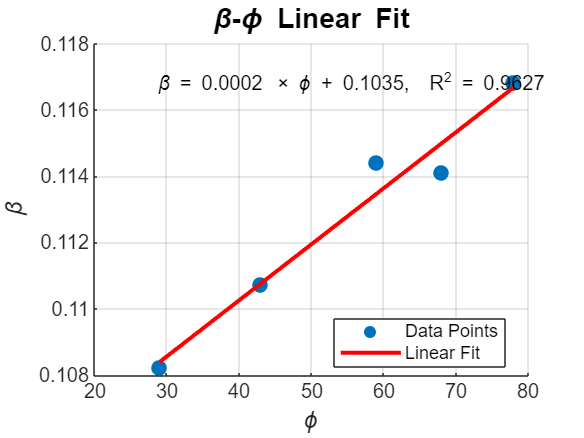

Linear Fit: beta = 0.000169 * phi + 0.103490
R-squared = 0.962698


base_dir = 'E:\LungFEM_Study\Results\RawData';
alpha_folders = {
    'B14_FZRH_E03E13_phi29_alpha5_tau25\Relax', ... 
    'B13_FZRH_E03E13_phi43_alpha5_tau25\Relax', ...
    'B03_FZRH_E03E13_phi59_alpha5_tau25\Relax', ...
    'B12_FZRH_E03E13_phi68_alpha5_tau25\Relax', ...
    'B11_FZRH_E03E13_phi78_alpha5_tau25\Relax', ...
    };
[phi_values, beta_values] = get_beta_for_phis(base_dir, alpha_folders);
% nonlinear fitting
% fit_beta_phi_relationship(phi_values, beta_values);
% 假设已从 get_beta_for_phis 得到 phi_values, beta_values

% 保存路径
save_csv_path = fullfile(base_dir, 'phi_beta_linear_fit.csv');

% 调用线性拟合函数
fit_beta_phi_linear(phi_values, beta_values, save_csv_path);